# Walelet Cross-Spectrum and Coherence for signals with non stationary periodicities

In this simple script we calculate the Wavelet Cross-Spectrum and Coherence of two synthetic signals using Grinsted at al. code.

***Last updated: Oct 18,2022***

## Signals Sampling and Duration

Let us first define the sampling and duration of our synthetic signal:

Fs = 1000;            % Sampling frequency [in Hz] 
T = 1/Fs;             % Sampling period [in seconds]   
L = 800;             % Length of signal [Number of samples]
t = (0:L-1)*T;        % Time vector [in s]

The next step is to generate the two synthetic signals, with time varyng periodicities, and one coponent varying at a common frequency

% Signal 1

A1=2;               % Amplitude [in a.u.]
f1=50;              % Frequency [in Hz]
A2=2;               % Amplitude [in a.u.]
f2=100;             % Frequency [in Hz]
s2n=4;

t1=t;
t1(L/2:end)=0;
t2=t;
t2(1:L/2-1)=0;

% Generate sinusoids
S1 = A1*sin(2*pi*f1*t1);
S2=A2*sin(2*pi*f2*t2);
S=S1+S2;
% Generate White Noise
Wn= sqrt(s2n)*randn(size(t));

% Generate the final signal as a sum of the two above
X1 = S + Wn;

% Signal 2
A3=3;               % Amplitude [in a.u.]
f3=100;             % Frequency [in Hz]
s2n=5;

t3=t;
t3(1:L/4)=0;
t3(3*L/4:end)=0;
S=A3*sin(2*pi*f3*t3);
% Generate White Noise
Wn= sqrt(s2n)*randn(size(t));

% Generate the final signal 
X2 = S + Wn;

Let us now plot the two noisy signals in the time domain:

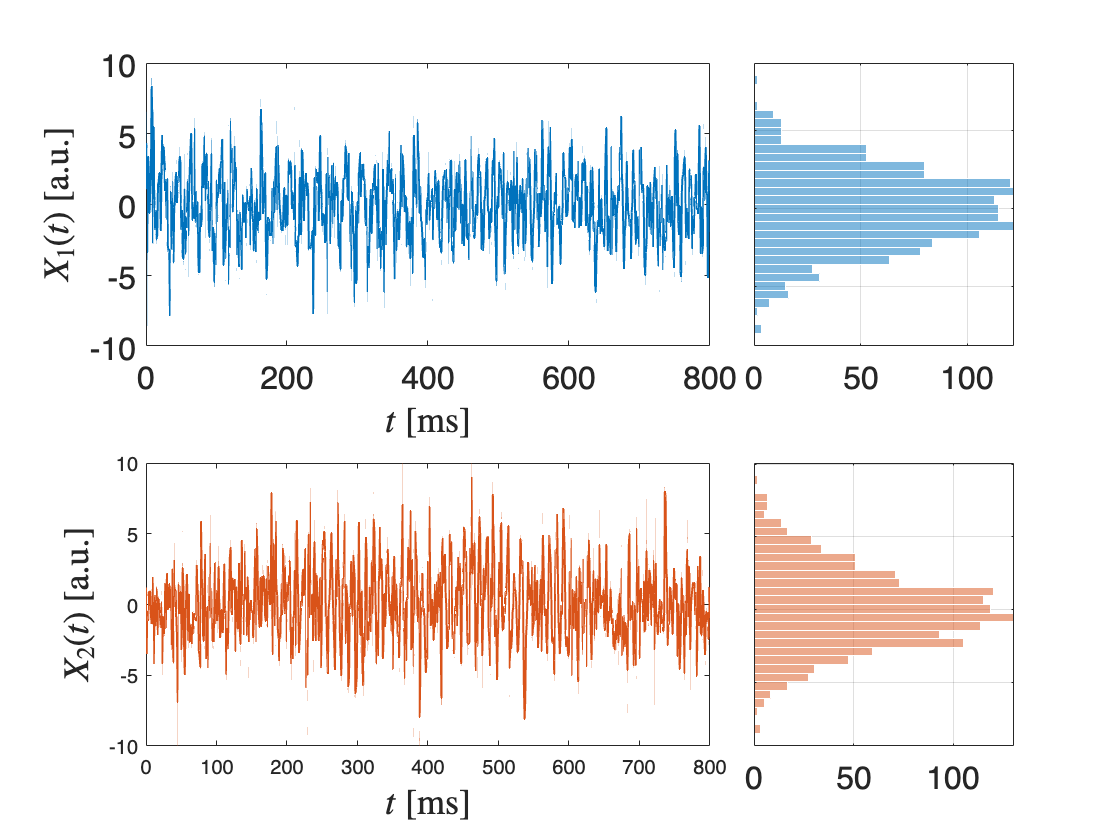

figure;
tiledlayout(2,3,'TileSpacing','compact');
nexttile([1,2]);
sfont=16;
h1=plot(1000*t,X1);
set(h1,'linewidth', 1);
set(gca,'FontSize',sfont);

% Axex labels
xlabel("$t$ [ms]","FontSize",sfont+2,'Interpreter','latex');
ylabel("$X_1(t)$ [a.u.]","FontSize",sfont+2,'Interpreter','latex');

nexttile;
%Hist 1
nb=30;
h1=histogram(X1,nb,'Normalization','countdensity','Orientation','horizontal');
set(gca,'FontSize',sfont,'YTickLabel',[]);
set(h1,'linewidth', .5,'FaceColor','#0072BD','EdgeColor','w','FaceAlpha',.5);
grid on;

nexttile([1,2]);
h2=plot(1000*t,X2);
set(h2,'linewidth', 1,'Color','#D95319');


% Axex labels
xlabel("$t$ [ms]","FontSize",sfont+2,'Interpreter','latex');
ylabel("$X_2(t)$ [a.u.]","FontSize",sfont+2,'Interpreter','latex');

hold off;
nexttile;
%Hist 2
h1=histogram(X2,nb,'Normalization','countdensity','Orientation','horizontal');
set(gca,'FontSize',sfont,'YTickLabel',[]);
set(h1,'linewidth', .5,'FaceColor','#D95319','EdgeColor','w','FaceAlpha',.5);
grid on;

## Next step: Test the series for Gaussianity

Are the time series normal?

[h1,p1,adstat1,cv1] = adtest(X1,'MCTol',0.01,'Alpha',0.05)

h1 = logical
   0


p1 = 0.4649

adstat1 = 0.3525

cv1 = 0.7420

[h2,p2,adstat2,cv2]= adtest(X2,'MCTol',0.01,'Alpha',0.05)

h2 = logical
   0


p2 = 0.0580

adstat2 = 0.7278

cv2 = 0.7551

## Wavelet Cross-spectrum

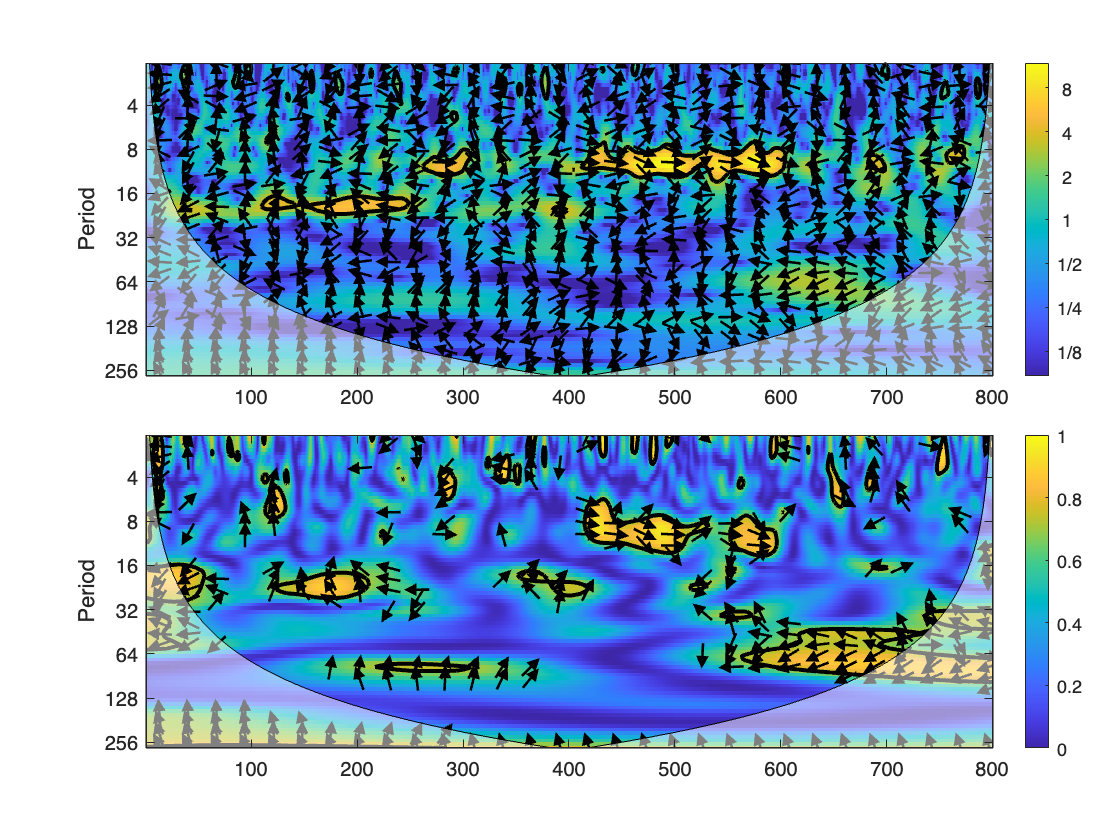

figure('color',[1 1 1])
tiledlayout(2,2,'TileSpacing','compact');
nexttile([1,2]);
xwt(X1,X2)
nexttile([1,2]);
wtc(X1,X2)